clc;
clear variables;
global my_camera;
mode = 1;

## 텔로 이륙하기

if (mode>0)
    my_tello = ryze()
    takeoff(my_tello);
    pause(3);   % wait for stability
else 
    my_tello = 0;
end

my_tello =   ryze - 속성 있음:

                   Name: "Tello"
                     ID: "TELLO-F0B35E"
              IPAddress: "192.168.10.1"
                  State: "landed"
           BatteryLevel: 80 %
            StationMode: 0
       AvailableCameras: ["FPV"]


## 영상 가져오기

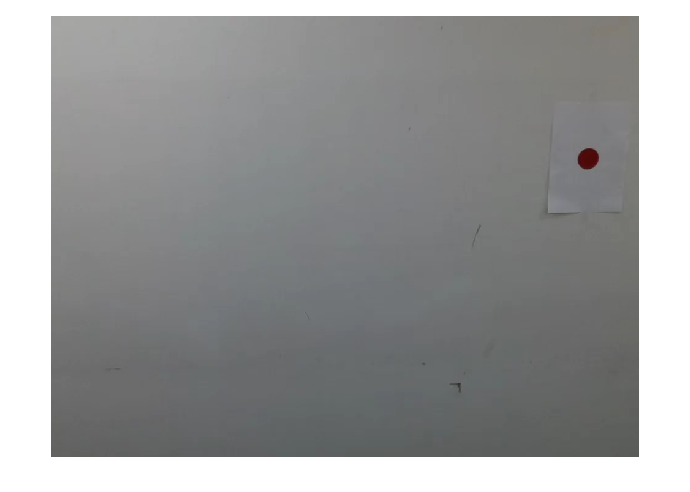

if (mode>0)                                    
    my_camera = camera(my_tello);                                                                                                                                                                                            
    img = snapshot(my_camera);
    imwrite(img, 'snapshot.png');
else
    %img = imread('snapshot.png');
end
imshow(img)

## **공 추적하고 주행**

[height, width, channels] = size(img);
center = [width/2, height/2]

center =    480   360


ball_pos =   877.7931  235.1910


ball_radius = 16.4799

ball_pos =   782.7156  406.0289


ball_radius = 18.5850

ball_pos =   642.9854  409.7738


ball_radius = 21.4475

ball_pos =   425.1948  489.5356


ball_radius = 24.1630

ball_pos =   390.5441  367.8898


ball_radius = 29.2499

done


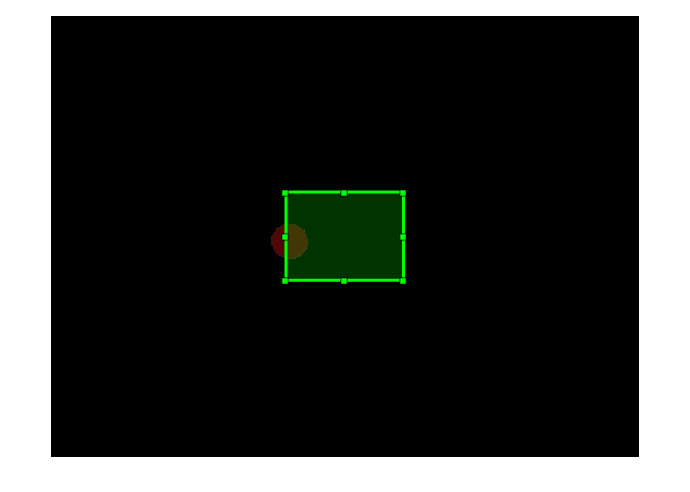

offset = [round(width/10), round(height/10)]; % round -> 반올림

flag = true;
while(flag)
    [ball_pos, ball_radius] = FindRedBall(img)
    if isempty(ball_pos) || isempty(ball_radius)
        disp('Could not find Red circle.')

        moveright(my_tello,'Distance',0.3)

        img = snapshot(my_camera);

        [ball_pos, ball_radius] = FindRedBall(img)
        
    elseif not(isempty(ball_pos)) || not(isempty(ball_radius))
        displace = (ball_pos - center);    
        [img, flag] = MoveAndSnap(mode, my_tello, img, displace, offset);
        drawrectangle('Position',[center-offset,offset*2],'Color',[0 1 0]);
        % a = input('press enter');
    end
end


ball_pos =

     []


ball_radius =

     []



Could not find Green circle.


ball_pos =   403.1233   22.4804


ball_radius = 27.5052

ball_pos =   403.1233   22.4804


ball_radius = 27.5052

ball_pos =   422.3758  208.5942


ball_radius = 30.4385

ball_pos =   457.8286  354.9612


ball_radius = 28.4529

done


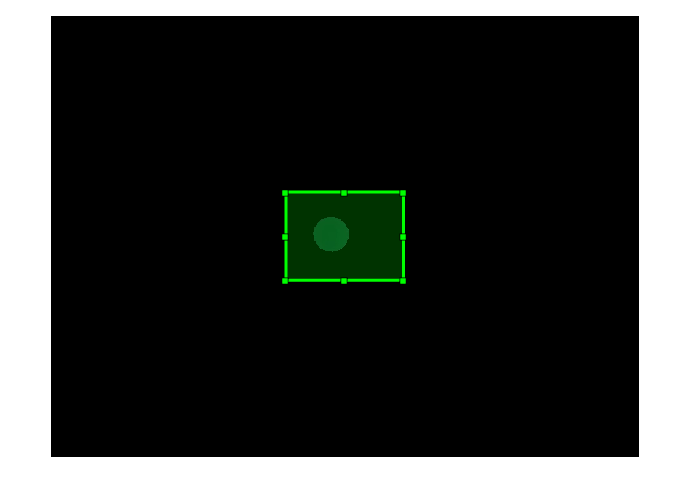


flag = true;
while(flag)
    [ball_pos, ball_radius] = FindGreenBall(img)
    if isempty(ball_pos) || isempty(ball_radius)
        disp('Could not find Green circle.')

        moveup(my_tello,'Distance',0.3)

        img = snapshot(my_camera);

        [ball_pos, ball_radius] = FindGreenBall(img)

    elseif not(isempty(ball_pos)) || not(isempty(ball_radius))
        displace = (ball_pos - center);    
        [img, flag] = MoveAndSnap(mode, my_tello, img, displace, offset);
        drawrectangle('Position',[center-offset,offset*2],'Color',[0 1 0]);
        % a = input('press enter');
    end
end


ball_pos =

     []


ball_radius =

     []



Could not find Blue circle.



ball_pos =

     []


ball_radius =

     []




ball_pos =

     []


ball_radius =

     []



Could not find Blue circle.


ball_pos =   361.7105  280.7367


ball_radius = 14.8547

ball_pos =   361.7105  280.7367


ball_radius = 14.8547


ball_pos =

     []


ball_radius =

     []



Could not find Blue circle.


ball_pos =   863.0518  373.3835


ball_radius = 36.4167

ball_pos =   863.0518  373.3835


ball_radius = 36.4167

ball_pos = 620.2626

ball_radius = 38.5769

ball_pos = 385.5311

ball_radius = 42.1084

done


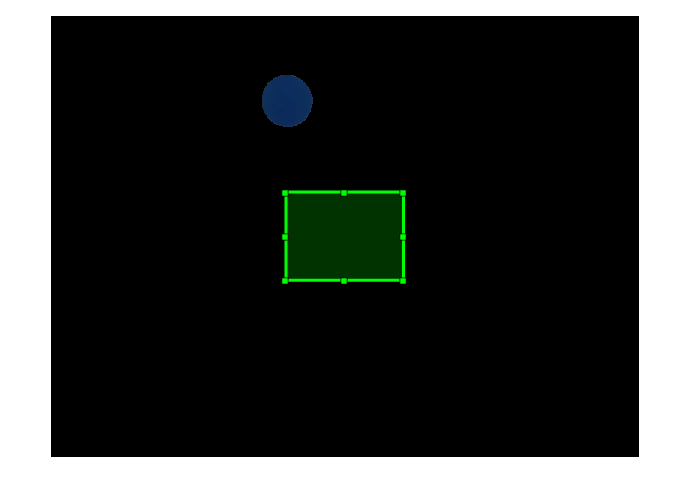


flag = true;
while(flag)
    [ball_pos, ball_radius] = FindBlueBall(img)
    if isempty(ball_pos) || isempty(ball_radius)
        disp('Could not find Blue circle.')

        moveright(my_tello,'Distance',0.3)

        img = snapshot(my_camera);

        [ball_pos, ball_radius] = FindBlueBall(img)

    elseif not(isempty(ball_pos)) || not(isempty(ball_radius))
        displace = (ball_pos - center);    
        [img, flag] = MoveAndSnap(mode, my_tello, img, displace, offset);
        drawrectangle('Position',[center-offset,offset*2],'Color',[0 1 0]);
        % a = input('press enter');
    end
end

## 텔로 착륙하기

if (mode>0)
    disp('All task is done.')
    land(my_tello);
end

All task is done.


% clear variables; 